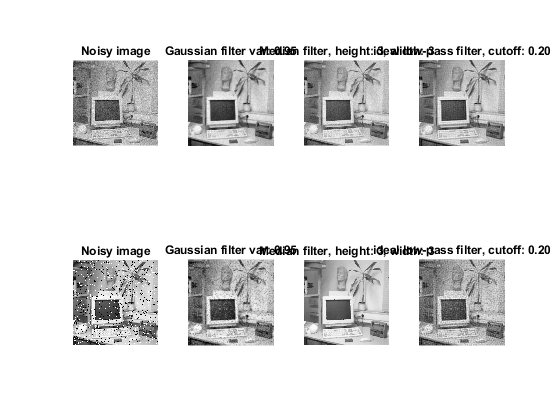

office = office256;
base = {gaussnoise(office,16), sapnoise(office,0.1,255)};
c = 1;
for b = 1:length(base)
    subplot(2,4,c);
    showgrey(base{b});
    title("Noisy image");
    subplot(2,4,c+1);
    var = 0.95;
    showgrey(gaussfft(base{b},var));
    title(sprintf("Gaussian filter var: %0.2f",var));
    subplot(2,4,c+2);
    wheight = 3;
    wwidth = 3;
    showgrey(medfilt(base{b},wheight,wwidth));
    title(sprintf("Median filter, height: %d, width: %d",wheight, wwidth));
    subplot(2,4,c+3);
    cutoff = 0.2;
    showgrey(ideal(base{b},cutoff));
    title(sprintf("ideal low-pass filter, cutoff: %0.2f", cutoff));
    c = c + 4;
end